clc; clear; close all
cd 'E:\Machine Learning\NW_image_quality_50tests_noramlized\train\1'
addpath 'F:\research\deep learning\deep_learning_images\SiNW_and_AgNW\test'
addpath 'E:\Jiaxu Flashdrive Backup\code\functions'
addpath 'F:\research\deep learning\deep_learning_images\Quality Est'

imds = imageDatastore("E:\Machine Learning\NW_image_quality_50tests\train\1");

for i = 1:length(imds.Files)
    I(:,:,i) = readimage(imds,i);
end

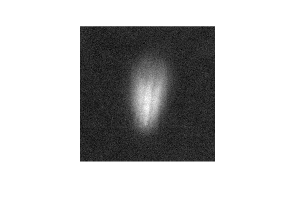

float_I = double(I);
scale_I = scale_image(float_I);
imshow(scale_I(:,:,round(rand(1)*50)));


[~,~,n] = size(scale_I); 

for i = 1:n
    imwrite(scale_I(:,:,i)...
        ,sprintf('E:\\Machine Learning\\NW_image_quality_50tests_noramlized\\train\\1\\%d.jpeg',i));
end